# **Análisis de supervivencia para cáncer de páncreas con datos transcriptómicos (TCGA-PDAC). **

# **Parte 1 - Control de calidad en las muestras**

### **¿Qué es un análisis de supervivencia?**

Un análisis de supervivencia es un análisis de "tiempo-a-evento" que responde de manera gráfica a la pregunta ¿Cuánto tiempo ocurre hasta que sucede el evento de interés?". En ciencias biológicas los eventos pueden ser: El tiempo de infección de un paciente desde su exposición, el tiempo de recuperación, recaída a la enfermedad o la muerte. 

*Censura. *

Un concepto importante en este tipo de análisis es el de "censura". Sobre todo en ensayos clínicos, el tiempo-a-evento puede no ser registrado debido a múltiples razones como: el término del ensayo o la ausencia del paciente al ensayo. En estos casos, el sujeto sobrevive a través del tiempo en el estudio y el tiempo exacto de supervivencia se vuelve desconocido, a esto se le llama "censura por la derecha". 

### Datos.

Los datos utilizados en este script provienen de la base de datos *THE CANCER GENOME ATLAS (TCGA). Para su descarga, *e creo una cohorte para la descarga de la expresión transcriptómica por paciente obtenida por la técnica *RNA-Seq *para adenocarcinoma ductal pancreático (PDAC). 

En este script se analizan los transcritos de 9 genes: **CREB1, MAPK7, MTSS1, PDGFRB, PTPN11, RB1, RICTOR, SRC, STAT3. **Que son de interés en cáncer de páncreas. 

### Descripción general del código. 

El siguiente código aplica a la cohorte actual los siguientes ocho filtros: *Solo tumor primario, un perfil por paciente, pacientes con datos clínicos disponibles, únicamente PDAC, pureza de las muestras, exclusión de muertes no oncológicas y de tejidos metastásicos. *Es recomendable aplicar un control de calidad previo al análisis de datos biológicos, pues las muestras no provienen exclusivamente de un centro de investigación, esto podría involucrar la aplicación de un protocolo distinto o un procesamiento diferente de las muestras, lo que podría alterar los resultados obtenidos y comprometer la validez biológica y estadística del análisis posterior [2]. 

El código genera como resultado una nueva cohorte de pacientes que participarán en el análisis de supervivencia en el código de nombre: "PAAD_supervivencia_KM_Cox". 

### Sección 0. Limpieza de *Command Window *y* Workspace. *

clear; clc; close all;

### Sección 1. Rutas y parámetros del análisis. 

Esta sección prepara el entorno de trabajo. Primero, se define la carpeta principal del proyecto (rutaBase) y, a partir de ella, con la función "fullfile", se construyen las rutas de todos los archivos que usará el script. Esos archivos son el *sample sheet* de GDC, que relaciona cada archivo de RNA-seq con su barcode de TCGA; el archivo clínico en formato .tsv y el de seguimiento, que aportan el estado vital, los tiempos de supervivencia y las características de cada paciente; el archivo de pureza tumoral ABSOLUTE de PanCanAtlas; y la tabla de expresión de los genes de interés generada por el script "Empalme_Anticuerpos_TPM". También se define la carpeta donde se guardarán los resultados.

Después, se fijan los parámetros que controlan los filtros de la cohorte. "modoPDAC" define qué se considera adenocarcinoma ductal pancreático: con la opción "excluir_NE" se conservan todas las histologías excepto los tumores neuroendocrinos, mientras que con "estricto" solo se conserva el carcinoma ductal infiltrante (morfología 8500/3). "umbralPureza" establece la pureza tumoral miníma, en este caso 0.30, para conservar una muestra. Tres variables lógicas funcionan como interruptores de filtros opcionales: con la configuración actual se excluyen las muestras sin dato de pureza, pero se conservan las muertes de causa desconocida y los pacientes sin estadio patológico. Por último, "diasPorMes" convierte los tiempos de supervivencia de días a meses.

rutaBase    = "C:\PAP Keyla Otoño 2026\Downloaded_Data_Cohort_Pancreas";
rutaSheet   = fullfile(rutaBase, "gdc_sample_sheet.2026-09-24.tsv");
rutaClinico = fullfile(rutaBase, "clinical.cart.2026-09-24", "clinical.tsv");
rutaFollow  = fullfile(rutaBase, "clinical.cart.2026-09-24", "follow_up.tsv");  % opcional
rutaPureza  = fullfile(rutaBase, "TCGA_mastercalls.abs_tables_JSedit.fixed.txt");
rutaTPM     = fullfile(rutaBase, "RPPA_genesInteres_TPM.csv");
carpetaSal  = fullfile(rutaBase, "Resultados_Supervivencia");

modoPDAC                = "excluir_NE"; % "excluir_NE": todo excepto neuroendocrinos
                                        % "estricto":   sólo 8500/3 (Infiltrating duct carcinoma)
umbralPureza            = 0.30;
excluirSinPureza        = true;   % muestras sin valor de pureza ABSOLUTE
excluirCausaDesconocida = false;  % muertes con causa de muerte desconocida
excluirSinEstadio       = false;  % pacientes sin estadio patológico
diasPorMes              = 30.4375;

if ~isfolder(carpetaSal), mkdir(carpetaSal); end

bitacora  = table('Size',[0 3], 'VariableTypes',["string","double","double"], ...
                  'VariableNames',["paso","perfiles","pacientes"]);
excluidos = table('Size',[0 3], 'VariableTypes',["string","string","string"], ...
                  'VariableNames',["paciente","sample_barcode","motivo"]);

### Sección 2. Perfiles de RNA-Seq: sample sheet + TPM de los genes de interés. 

La segunda sección reúne las dos fuentes que identifican cada perfil de RNA-Seq: el sample sheet de GDC y la tabla de expresión de los genes de interés. El objetivo es que cada perfil quede asociado con su barcode TCGA, el ID del paciente y el tipo de muestra, que son la base los filtros siguientes. 

Primero se lee el sample sheet con la función "leerTSVtext", que carga todas las columnas como texto y conserva los nombres originales de las columnas. El sample sheet describe todos los archivos de la descarga de GDC, así que se filtra para quedarse solo con las filas cuyo nombre del archivo termina en "augmented_star_gene_counts.tsv", es decir, los archivos de expresión génica de STAR. 

Después se lee "RPPA_genesInteres_TPM.csv", la tabla generada por el script de "Empalme_Anticuerpos_TPM", con una fila por archivo de RNA-seq- Sus dos primeras columnas son identificadores (file_uuid y sample_id) y las demás son los genes. Por eso los nombres se obtienen a partir de la tercera columna, y el script imprime cuántos genes encontró y cuáles son.

Luego se relacionan las dos tablas. El "file_uuid" de cada perfil (el nombre de la carpeta descargada de GDC) es el mismo identificador que aparece en la columna "File ID" del sample sheet. Con "ismember" se busca cada "file_uuid" en esa columna: "hay" indica si se encontró y "j" en qué fila. Si algún perfil no aparece en el sample sheet, el script muestra una advertencia y lo descarta, porque sin su barcode no podría asociarse con los datos clínicos. 

Para los perfiles encontrados se agregan tres columnas a partir del barcode TCGA. "sample_barcode" es el identificador completo de la muestra, tomado de la columna "Sample ID". "paciente" corresponde a sus primeros 12 caracteres, que identifican al paciente y sirven para unir con el archivo clínico. "tipo_muestra" corresponde a los caracteres 14 y 15, el código que indica si la muestra es tumor primario (01). tejido normal o metástasis (06). Esta columna se utiliza en el filtro de la sección 3. 

Por último, se registra la primera fila de la bitácora: el punto de partida, con el número total de perfiles de RNA-seq y de pacientes distintos antes de aplicar cualquier filtro. Ese conteo también se imprime en la Command Window. 

S = leerTSVtexto(rutaSheet);
S = S(endsWith(S.("File Name"), "augmented_star_gene_counts.tsv"), :);

TPMv  = readtable(rutaTPM, 'TextType','string', 'VariableNamingRule','preserve');
genes = string(TPMv.Properties.VariableNames(3:end));
fprintf("Genes en el archivo TPM (%d): %s\n\n", numel(genes), strjoin(genes, ", "));

Genes en el archivo TPM (9): PDGFRB, CREB1, RB1, RICTOR, MAPK7, STAT3, MTSS1, PTPN11, SRC




% La carpeta UUID (file_uuid) es el "File ID" del sample sheet
[hay, j] = ismember(TPMv.file_uuid, S.("File ID"));
if any(~hay)
    warning("%d perfiles del archivo TPM no están en el sample sheet; se descartan.", sum(~hay));
end
perf = TPMv(hay, :);
perf.sample_barcode = S.("Sample ID")(j(hay));               % TCGA-XX-XXXX-01A
perf.paciente       = extractBefore(perf.sample_barcode, 13); % TCGA-XX-XXXX
perf.tipo_muestra   = extractBetween(perf.sample_barcode, 14, 15);

bitacora(end+1,:) = {"Perfiles RNA-seq (STAR)", height(perf), numel(unique(perf.paciente))};
fprintf("%-42s -> %4d perfiles | %4d pacientes\n", bitacora.paso(end), bitacora.perfiles(end), bitacora.pacientes(end));

Perfiles RNA-seq (STAR)                    ->  178 perfiles |  178 pacientes


### Sección 3. Filtro 1: solo tumor primario. 

Esta sección aplica el primer filtro: conservar solo las muestras de tumor primario. En TCGA, el tipo de muestra está codificado en los caracteres 14 y 15 del barcode, que en la sección anterior se guardaron en la columna "tipo_muestra". El código 01 corresponde a un tumor sólido primario, 11 a tejido normal adyacente y 06 a metástasis. Este filtro es importante porque el tejido normal y las metástasis tiene perfiles de expresión distinto al del tumor original. Si se mezclaran, los pacientes no serían comparables entre sí. 

Antes de filtrar, "groupcounts" imprime una tabla con cuántas muestras hay de cada tipo. Así se puede observar cuántas muestras se van a eliminar. Si todas son 01, el filtro no quita ninguna, pero documenta que la cohorte solo incluye tumores primarios. 

El filtro se aplica con la función "filtrar", definida al final del script y que se reutiliza en todas las secciones siguientes. Recibe la tabla de perfiles y un vector lógico que marca qué fila conservar: aquí es "perf.tipo_muestra == "01"", que verdadero solo para los tumores primarios. También recibe un texto con el nombre del paso (Tumor primario (01)) y otro con el motivo de exclusión ("No es tumor primario"). 

La función hace tres cosas. Primero agrega a la tabla "excluidos" una fila por cada muestra eliminada, con su paciente, su barcode y el motivo. Luego conserva en "perf" solo las filas que cumplen con la condición. Por último, agrega una fila a la "bitacora" con el nombre del paso y el número de perfiles y de pacientes que quedan, e imprime ese resumen en la Command Window junto con cuántas muestras se excluyeron. 

% Código de tipo de muestra en el barcode: 01 = tumor sólido primario,
% 11 = tejido normal, 06 = metástasis, etc.
disp(groupcounts(perf, "tipo_muestra"));

    tipo_muestra    GroupCount    Percent
    ____________    __________    _______

        "01"           178          100  



[perf, excluidos, bitacora] = filtrar(perf, perf.tipo_muestra == "01", ...
    "Tumor primario (01)", "No es tumor primario", excluidos, bitacora);

Tumor primario (01)                        ->  178 perfiles |  178 pacientes (excluidos: 0)


### Sección 4. Filtro 2: un perfil por paciente

Esta sección del código garantiza que cada paciente aparezca una sola vez en la cohorte. En TCGA un mimso paciente puede tener más de un perfil de RNA-seq de tumor primario, por ejemplo dos viales de la misma muestra (A y B) o de dos porciones del tumor secuenciadas por separado. Si se conservaran todos, ese paciente contaría doble en el análisis de supervivencia. Su tiempo y su evento pesarían más que los de los demás, y se violaría el supuesto de que las observaciones son independientes. 

Para decidir qué perfil conservar se usa una regla fija, de modo que el resultado sea siempre el mismo. Primero, "sortrows" ordena la tabla por paciente, luego por barcode de la muestra y, si hay empate, por UUID del archivo. Como la letra del vial va al final del barcode (-01A o -01B), en ese orden el vial A queda antes que el B. Después, "unique(perf.paciente, 'first')" devuelve la posición de la primera aparición de cada paciente en la tabla ya ordenada. Así se elige el vial A cuando existe, o el primer barcode en orden alfabético en caso de empate. 

Con esas posiciones se construye el vector lógico "conservar". Se crea lleno de "false", con una entrada por perfil, y se cambia a "true" solo en las posiciones elegidas. Los perfiles que quedan en "false" son los duplicados. 

Si hay algún paciente con más de un perfil, el código imprime todos sus perfiles (paciente, barcode y UUID) antes de eliminar los sobrantes. Así puedes revisar que perfil se conservó y cuál se descartó. Si no hay duplicados, no se imprime nada. 

Por último, la función "filtrar" aplica la selección: registra los perfiles eliminados en la tabla "excluidos" con el motivo "Perfil duplicado del paciente", conserva solo los perfiles elegidos y agrega el paso a la bitácora. Después de este filtro, el número de perfiles y el de pacientes deben ser iguales. 

% Si un paciente tiene más de un perfil tumoral, se conserva el vial A antes
% que el B, C...; con empate, el primero en orden alfabético del barcode.
perf = sortrows(perf, ["paciente","sample_barcode","file_uuid"]);
[~, iPrim] = unique(perf.paciente, 'first');
conservar  = false(height(perf), 1);  conservar(iPrim) = true;

if any(~conservar)
    fprintf("Pacientes con más de un perfil tumoral:\n");
    disp(perf(ismember(perf.paciente, perf.paciente(~conservar)), ["paciente","sample_barcode","file_uuid"]));
end
[perf, excluidos, bitacora] = filtrar(perf, conservar, ...
    "Un perfil por paciente", "Perfil duplicado del paciente", excluidos, bitacora);

Un perfil por paciente                     ->  178 perfiles |  178 pacientes (excluidos: 0)


### Sección 5. Datos clínicos: una fila por paciente. 

Esta quinta sección prepara los datos clínicos. El archivo clinical.tsv de GDC tiene dos problemas para el análisis. Primero, repite a cada paciente en varias filas, una por cada combinación de diagnóstico y tratamiento. Segundo, marca los datos faltantes con textos como '--'. Esta sección limpia el archivo y lo resume en una tabla con una fila por paciente "clin" que contiene solo las variables que necesita el análisis de supervivencia. A diferencia de las secciones anteriores, aquí no se excluye a ningún paciente ni se agrega nada a la bitácora, solo se prepara la información. 

Primero se lee el archivo clínico y se define la lista de columnas necesarias: el ID del paciente, la fecha de referencia (index_date), el estado vital, los días hasta la muerte, la causa de muerte, la edad, los días hasta el último seguimiento, el diagnóstico, la morfología, el estadio patológico, la categoría M (metastasis) y la columna que indica si el diagnóstico es la enfermedad primaria.

Luego el código verifica que todas esas columnas existan. Si falta alguna, se detiene con un error que dice cuál. para que no siga trabajando con un archivo incompleto con otro formato. Después, la función limpiar convierte en faltantes "missing" los valores vacíos y los textos '--, Not Reported y unknow, de modo que los datos faltantes queden representados igual. 

También se eliminan las filas de diagnóstico que no corresponden a la enfermedad primaria, es decir, las marcadas como "false" en la columna de diagnóstico primario. Así, la información del tumor corresponde al cáncer de páncreas y no a otro diagnóstico del mismo paciente. 

Para reducir el archivo a una fila por paciente, se obtiene la lista de pacientes únicos "pacs", y con "ismember" se calcula el vector "g", que indica a qué paciente pertenece cada fila del archivo. Las columnas se dividen en dos grupos y se renombran con nombres cortos en español: las de texto y las númericas. La tabla "clin" se crea con una fila por paciente, llena de faltantes, y después se completa paciente por paciente. Para las columnas de texto se toma el primer vaor no faltante de sus filas. Para las númericas se toma el valor máximo, ignorando los faltantes. Esto es importante en el seguimiento: si las filas de un paciente registran distintos días de último contacto, se usa el más reciente.

Si existe el archivo follow_up.tsv, se usa para completar el último seguimiento. Para cada paciente se compara el valor obtenido de clinical.tsv con todos los días de seguimiento registrados en follow_up.tsv, y se conserva el mayor. Esto evita subestimar el tiempo de observación de los pacientes vivos, porque a veces las visitas más recientes solo aparecen en ese archivo.

Por último, el script imprime cuántos pacientes tiene el archivo clínico y una tabla con los "valores de index_date". Esa tabla es un control de calidad: confirma que los días de muerte y de seguimiento se cuentan desde el diagnóstico, que es el punto de partida correcto para la supervivencia global.

% clinical.tsv de GDC repite cada caso por diagnóstico y tratamiento, y usa
% '-- para los vacíos. Aquí se limpia y se colapsa a una fila por paciente.
C = leerTSVtexto(rutaClinico);
cols = ["cases.submitter_id","cases.index_date", ...
        "demographic.vital_status","demographic.days_to_death", ...
        "demographic.cause_of_death","demographic.age_at_index", ...
        "diagnoses.days_to_last_follow_up","diagnoses.primary_diagnosis", ...
        "diagnoses.morphology","diagnoses.ajcc_pathologic_stage", ...
        "diagnoses.ajcc_pathologic_m","diagnoses.diagnosis_is_primary_disease"];
faltan = setdiff(cols, string(C.Properties.VariableNames));
if ~isempty(faltan)
    error("Columnas no encontradas en clinical.tsv: %s", strjoin(faltan, ", "));
end
for c = cols, C.(c) = limpiar(C.(c)); end

% Quitar las filas de diagnósticos que no son la enfermedad primaria
esPrim = lower(C.("diagnoses.diagnosis_is_primary_disease"));
C = C(ismissing(esPrim) | esPrim ~= "false", :);

pacs = unique(C.("cases.submitter_id"));
pacs = pacs(~ismissing(pacs));
n    = numel(pacs);
[~, g] = ismember(C.("cases.submitter_id"), pacs);

colsTxt = ["cases.index_date","demographic.vital_status","demographic.cause_of_death", ...
           "diagnoses.primary_diagnosis","diagnoses.morphology", ...
           "diagnoses.ajcc_pathologic_stage","diagnoses.ajcc_pathologic_m"];
nomTxt  = ["index_date","vital_status","causa_muerte","diagnostico","morfologia","estadio","ajcc_m"];
colsNum = ["demographic.days_to_death","demographic.age_at_index","diagnoses.days_to_last_follow_up"];
nomNum  = ["dias_muerte","edad","dias_ult_seguimiento"];

clin = table(pacs, 'VariableNames', "paciente");
for k = 1:numel(nomTxt), clin.(nomTxt(k)) = repmat(string(missing), n, 1); end
for k = 1:numel(nomNum), clin.(nomNum(k)) = NaN(n, 1);                end
for p = 1:n
    filas = (g == p);
    for k = 1:numel(colsTxt), clin.(nomTxt(k))(p) = primerValor(C.(colsTxt(k))(filas)); end
    for k = 1:numel(colsNum), clin.(nomNum(k))(p)  = max(str2double(C.(colsNum(k))(filas)), [], 'omitnan'); end
end

% Último seguimiento: también se revisa follow_up.tsv (si existe) y se toma el máximo
if isfile(rutaFollow)
    F    = leerTSVtexto(rutaFollow);
    colF = "follow_ups.days_to_follow_up";
    if ismember(colF, string(F.Properties.VariableNames))
        [~, gf] = ismember(limpiar(F.("cases.submitter_id")), pacs);
        dF      = str2double(limpiar(F.(colF)));
        for p = 1:n
            clin.dias_ult_seguimiento(p) = max([clin.dias_ult_seguimiento(p); dF(gf == p)], [], 'omitnan');
        end
        fprintf("Último seguimiento complementado con follow_up.tsv\n");
    end
end

Último seguimiento complementado con follow_up.tsv



fprintf("Pacientes en clinical.tsv: %d\n", n);

Pacientes en clinical.tsv: 178


fprintf("index_date (los días deben contarse desde el diagnóstico):\n");

index_date (los días deben contarse desde el diagnóstico):


disp(groupcounts(clin, "index_date"));

    index_date     GroupCount    Percent
    ___________    __________    _______

    "Diagnosis"       178          100  



### Sección 6. Filtro 3: con datos clínicos. 

 La sexta sección une las dos piezas que se prepararon por separado: los perfiles de expresión "perf", con una fia por paciente después del filtro anterior, y los datos clínicos "clin", también con una fila por paciente. El resultado es la tabla "coh", la cohorte de trabajo. Ahí cada paciente tiene en una misma fila sus identificadores, la expresión de los genes de interés y su información clínica. Todos los filtros siguiente se aplican sobre esta tabla. 

La unión se hace por el ID del paciente. Con "ismember", cada paciente de "perf" se busca en la tabla clínica, y se obtienen dos resultados. "enClin" es un vector lógico que indica si el paciente tiene datos clinicos. "j" indica en qué fila de "clin" están estos datos. 

Después se aplica el filtro con la función "filtrar": se conservan solo los pacientes con datos clínicos y los demás se registran en "excluidos" con el motivo "Sin datos clínicos" . La razón es que un paciente con expresión pero sin información clínica no tiene tiempo de supervivencia ni estado vital, así que no puede entrar al análisis. 

Por último, se construye "coh" pegando lado a lado la tabla de perfiles ya filtrada y las filas correspondientes de la tabla clínica. Las posiciones "j(enClin)" toman, de "clin", solo las filas de los pacientes que se conservaron y en el mismo orden que "perf", de modo que cada fila clínica queda alineada con su paciente. De "clin" se toman las columnas de la segunda en adelante para no repetir el ID del paciente, que ya está en perf. 

Como los perfiles de RNA-seq y lo datos clínicos vienen de la misma descarga de GDC, lo esperado es que todos los pacientes tengan datos clínicos. En ese caso este filtro no excluye a nadie, y la bitácora muestra el mismo número de pacientes que en el paso anterior. 

[enClin, j] = ismember(perf.paciente, clin.paciente);
[perf, excluidos, bitacora] = filtrar(perf, enClin, ...
    "Con datos clínicos", "Sin datos clínicos", excluidos, bitacora);

Con datos clínicos                         ->  178 perfiles |  178 pacientes (excluidos: 0)


coh = [perf, clin(j(enClin), 2:end)];

### Sección 7. Filtro 4: sólo PDAC

Esta sección deja en la cohorte solo a los pacientes con PDAC. El proyecto TCGA-PAAD incluye todos los tumores primarios de páncreas y no todos son PDAC: algunos son tumores neuroendocrinos. Se originan en células distintas, tienen otra biología y su pronóstico suele ser mucho mejor. Si se mezclaran con los PDAC, alargarían artificialmente la supervivencia de la cohorte y podrían crear asociaciones falsas entre la expresión génica y el pronóstico. 

Antes de filtrar, el script imprime "groupcounts" una tabla con todas las combinaciones de diagnóstico y morfología presentes en la cohorte, y cuántos pacientes hay de cada una. Después se identifican los tumores neuroendocrinos con dos criterios, para no depender de una sola columna: que el código de morfología ICD-O empiece con "824" (la familia de los tumores neuroendocrinos) o que el texto del diagnóstico contenga la palabra "neuroendocrine". Basta con que se cumpla uno para marcar al paciente con el vector lógico "esNE". 

Por último, la función "filtrar" conserva solo a los pacientes marcados como PDAC, registra a los demás en "excluidos" con el motivo "No es PDAC" y agrega el paso a la bitácora. En el nombre del paso queda indicado qué criterio se usó, por ejemplo "PDAC (excluir_NE)".  

fprintf("Histologías en la cohorte:\n");

Histologías en la cohorte:


disp(groupcounts(coh, ["diagnostico","morfologia"]));

                diagnostico                 morfologia    GroupCount    Percent
    ____________________________________    __________    __________    _______

    "Adenocarcinoma with mixed subtypes"     "8255/3"          1        0.5618 
    "Adenocarcinoma, NOS"                    "8140/3"         20        11.236 
    "Carcinoma, undifferentiated, NOS"       "8020/3"          1        0.5618 
    "Infiltrating duct carcinoma, NOS"       "8500/3"        143        80.337 
    "Mucinous adenocarcinoma"                "8480/3"          5         2.809 
    "Neuroendocrine carcinoma, NOS"          "8246/3"          8        4.4944 




esNE = startsWith(coh.morfologia, "824") | contains(lower(coh.diagnostico), "neuroendocrine");
switch modoPDAC
    case "excluir_NE"
        esPDAC = ~esNE & ~ismissing(coh.diagnostico);
    case "estricto"
        esPDAC = startsWith(coh.morfologia, "8500");
    otherwise
        error("modoPDAC debe ser ""excluir_NE"" o ""estricto"".");
end
[coh, excluidos, bitacora] = filtrar(coh, esPDAC, ...
    "PDAC (" + modoPDAC + ")", "No es PDAC", excluidos, bitacora);

PDAC (excluir_NE)                          ->  170 perfiles |  170 pacientes (excluidos: 8)


### Sección 8. Filtro 5: pureza tumoral ABSOLUTE (PanCanAtlas)

Esta sección aplica el filtro de pureza tumoral. La pureza es la fracción de células tumorales en la muestra, el resto son células del estroma. En PDAC la pureza suele ser baja porque el tumor esta rodeado de mucho estroma. Cuando la pureza es muy baja, la expresión medida en el RNA-Seq refleja más al tejido que rodea al tumor que a las células tumorales. Por eso esas muestras se excluyen. 

Los valores de pureza vienen del archivo de ABSOLUTE del PanCanAtlas, un algoritmo que estima la pureza de cada muestra a partir de los datos de número de copias del ADN [3]. El script lee el archivo y verifica que tenga las dos columnas que necesita: "array", con el identificador de la muestra, y "purity", con el valor de pureza. Si falta alguna, se detiene con un error que muestra las columnas que sí encontró. Después limpia lo valores faltantes, convierte la pureza a número y, si alguna muestra aparece repetida en el archivo, conserva solo su primera aparición. 

Para unir la pureza con la cohorte hay que usar el identificador correcto. El archivo ABSOLUTE identifica cada muestra con los primeros 15 caracteres del barcode, es decir, el paciente más el tipo de muestra, sin la letra del vial. El script crea en la cohorte la columna "muestra15" con esos mismos caracteres. Con "ismember" busca cada muestra en el archivo de pureza y guarda el valor en la nueva columna "pureza". Las muestras sin pureza quedan con "NaN". 

Antes de filtrar, el script imprime un resumen: cuántas muestras tienen dato de pureza, la mediana de pureza y cuántas quedan por debajo del umbral. También genera un histograma con la distribución de la pureza y una línea roja que marca el umbral (0.30), y lo guarda como "QC_pureza.png". La figura muestra cuántas muestras se pierden con el filtro y qué tan baja es la pureza típica de la cohorte. 

Por último, se aplica el filtro. El vector lógico "pasaPureza" es verdadero para las muestras con pureza mayor o igual al umbral. Como una comparación con "Nan" siempre da false, las muestras sin dato quedan excluídas automáticamente. Si en la sección 1 se cambiara "excluirSinPureza" a "false" esas muestras se conservarían. La función "filtrar" conserva las muestras que pasan, registra las demás en "excluidos" con el motivo "Pureza baja o sin dato" y agrega el paso a la bitácora. Este filtro es el que más pacientes filtra. 

P = leerTSVtexto(rutaPureza);
if ~all(ismember(["array","purity"], string(P.Properties.VariableNames)))
    error("El archivo de pureza no tiene las columnas 'array' y 'purity'. Columnas: %s", ...
          strjoin(string(P.Properties.VariableNames), ", "));
end
P.array  = limpiar(P.array);
P.pureza = str2double(limpiar(P.purity));
[~, iu]  = unique(P.array, 'first');
P = P(iu, :);

coh.muestra15 = extractBefore(coh.sample_barcode, 16);
[hay, j] = ismember(coh.muestra15, P.array);
coh.pureza = NaN(height(coh), 1);
coh.pureza(hay) = P.pureza(j(hay));

fprintf("Pureza ABSOLUTE disponible: %d de %d | mediana = %.2f | < %.2f: %d\n", ...
    sum(~isnan(coh.pureza)), height(coh), median(coh.pureza, 'omitnan'), ...
    umbralPureza, sum(coh.pureza < umbralPureza));

Pureza ABSOLUTE disponible: 150 de 170 | mediana = 0.40 | < 0.30: 40


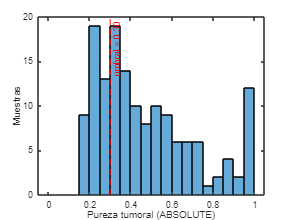


fig = figure('Name','QC pureza');
histogram(coh.pureza, 0:0.05:1);
xline(umbralPureza, 'r--', sprintf('umbral = %.2f', umbralPureza), 'LineWidth', 1.5);
xlabel('Pureza tumoral (ABSOLUTE)'); ylabel('Muestras');
title(sprintf('Pureza antes del filtro (n = %d con dato)', sum(~isnan(coh.pureza))));
exportgraphics(fig, fullfile(carpetaSal, "QC_pureza.png"), 'Resolution', 300);


pasaPureza = coh.pureza >= umbralPureza;   % NaN -> false
if ~excluirSinPureza, pasaPureza = pasaPureza | isnan(coh.pureza); end
[coh, excluidos, bitacora] = filtrar(coh, pasaPureza, ...
    sprintf("Pureza >= %.2f", umbralPureza), "Pureza baja o sin dato", excluidos, bitacora);

Pureza >= 0.30                             ->  110 perfiles |  110 pacientes (excluidos: 60)


### Sección 9. Filtro 6: exclusión de muertes no relacionadas al cáncer

Esta sección excluye a los pacientes que murieron por una causa ajena al cáncer. En el análisis de supervivencia global, cada muerte cuenta como evento. Pero si un paciente murió por una enfermedad cardiovascular o una complicación no relacionada con el tumor, esa muerte no dice nada sobre la agresividad del cáncer ni sobre el efecto de la expresión de los genes. Incluir esas muestras como evento añadiría ruido al análisis. 

Antes de filtrar, el script imprime una tabla con las causas de muerte registradas entre los pacientes fallecidos y cuántos hay de cada una. Así se puede observar qué causas aparecen en tus datos y qué tan completa está esa información. 

Después se construyen varios vectores lógicos. "muerto" identifica a los pacientes con estado vital "Dead" y "causaOnco" marca a los que tienen registrada la causa "Cancer Related". "causaDesc" marca a los pacientes sin causa registrada. Aquí entran tanto los campos vacíos como lo que decían "Unknown" o "Not Reported", porque la función "limpiar" de la sección 5 los convirió todos en faltantes. A partir de estos vectores, "noOnco" identifica a los pacientes que murieron y tienen una causa registrada distinta de cáncer. 

El vector "quitar" define a quién se elimina. Siempre incluye las muertes no oncológicas. Las muertes de causa desconocida solo se incluyen si en la sección 1 se puso "excluirCausaDesconocida = true". En la configuración actual de este código, estos pacientes se conservan, porque no hay forma de saber si murieron por el cáncer o por otra causa, y eliminarlos reduciría mucho la cohorte. El script imprime cuántas muertes no oncológicas y cuántas de causa desconocida hay e indica si las últimas se excluyeron. 

Por último, la función "filtrar" conserva a todos los pacientes que no están marcados en "quitar", registra a los eliminados en "excluidos" con el motivo "Muerte no relacionada al cáncer" y agrega el paso a la bitácota. Los pacientes vivos nunca se excluyen en este filtro, porque solo se evalúa a los fallecidos,

fprintf("Causa de muerte (pacientes Dead):\n");

Causa de muerte (pacientes Dead):


disp(groupcounts(coh(coh.vital_status == "Dead", :), "causa_muerte"));

          causa_muerte          GroupCount    Percent
    ________________________    __________    _______

    "Cancer Related"                45        70.312 
    "Not Cancer Related"             3        4.6875 
    "Surgical Complications"         3        4.6875 
    <missing>                       13        20.312 




muerto    = coh.vital_status == "Dead";
causa     = lower(coh.causa_muerte);
causaOnco = causa == "cancer related";
causaDesc = ismissing(causa);
noOnco    = muerto & ~causaOnco & ~causaDesc;
quitar    = noOnco | (excluirCausaDesconocida & muerto & causaDesc);
fprintf("Muertes no oncológicas: %d | con causa desconocida: %d (excluidas: %s)\n", ...
    sum(noOnco), sum(muerto & causaDesc), string(excluirCausaDesconocida));

Muertes no oncológicas: 6 | con causa desconocida: 13 (excluidas: false)



[coh, excluidos, bitacora] = filtrar(coh, ~quitar, ...
    "Sin muertes no oncológicas", "Muerte no relacionada al cáncer", excluidos, bitacora);

Sin muertes no oncológicas                 ->  104 perfiles |  104 pacientes (excluidos: 6)


### Sección 10. Filtro 7: exclusión de estadio IV (metástasis)

Esta décima sección del código excluye a los pacientes con enfermedad en estadio IV, es decir, con metástasis. En el cáncer de páncreas, el estadio IV cambia por completo la situación del paciente. La mayoría de los pacientes no se operan, reciben otro tipo de tratamiendo y su supervivencia es mucho más corta. Si se mezclaran con los pacientes de enfermedad localizada, el estadio dominaría en pronóstico y sería más difícil ver el efecto de la expresión de los genes. Excluirlos deja una cohorte más homogénea, de enfermedad localizada o localmente avanzada, que es el tipo de paciente que predomina en TCGA-PAAD porque sus muestras provienen de cirugías. 

Antes de filtrar, el script imprime con "groupcounts" una tabla con los estadios patológicos AJCC de la cohorte ("Stage IA, Stage IIB, Stage IV, etc.) y cuántos pacientes hay en cada uno. 

Para identificar a los pacientes con metastasis se usan dos columnas del archivo clínico para no depender de una sola. El vector lógico "esIV" marca a un paciente si su estadio patológico empieza con "Stage IV" o si su categoría M empieza con "M1". En la clasificación TNM, la M indica metástasis a distancia: M0 significa sin metástasis y M1 signfica con metástasis. Revisar ambas columnas sirve para atrapar a pacientes cuyo estadio global quedó vacío pero cuya categoría M sí indica metástasis. El vector "sinEstadio" marca a los pacientes sin estadio registrado. 

El script imprime cuántos pacientes están en el estadio IV o M1 y cuántos no tienen estadio, e indica si estos ultimos se excluyen. En la configuración actual del código, los pacientes sin estadio se conservan porque no hay evidencia de que tengan metástasis. 

Por último, la función "filtrar" conserva a los pacientes que no complen con la condición de exclusión, registra a los eliminados en "excluidos" con el motivo "Estadio IV/M1" y agrega el paso a la bitácora. 

fprintf("Estadio patológico AJCC:\n");

Estadio patológico AJCC:


disp(groupcounts(coh, "estadio"));

      estadio      GroupCount    Percent
    ___________    __________    _______

    "Stage IA"          3        2.8846 
    "Stage IB"          6        5.7692 
    "Stage IIA"        17        16.346 
    "Stage IIB"        71        68.269 
    "Stage III"         2        1.9231 
    "Stage IV"          3        2.8846 
    <missing>           2        1.9231 




esIV       = startsWith(coh.estadio, "Stage IV") | startsWith(coh.ajcc_m, "M1");
sinEstadio = ismissing(coh.estadio);
fprintf("Estadio IV o M1: %d | sin estadio: %d (excluidos: %s)\n", ...
    sum(esIV), sum(sinEstadio), string(excluirSinEstadio));

Estadio IV o M1: 3 | sin estadio: 2 (excluidos: false)



[coh, excluidos, bitacora] = filtrar(coh, ~(esIV | (excluirSinEstadio & sinEstadio)), ...
    "Sin estadio IV", "Estadio IV / M1", excluidos, bitacora);

Sin estadio IV                             ->  101 perfiles |  101 pacientes (excluidos: 3)


### Sección 11. Variables de supervivencia (OS) y filtro 8: datos válidos

Esta sección construye a las dos variables del análisis de supervivencia global (OS), revisa que sean coherentes y aplica el último filtro, que elimina a los pacientes cuyos datos de supervivencia no son válidos. 

Primero se crea el evento: vale 1 si el estado vital del paciente es "Dead" y 0 si sigue vivo. Los pacientes con "0" son censurados, es decir, se sabe que estaban vivos en su último contacto pero no qué pasó después. Luego se crea el tiempo. Para los vivos es el número de días desde el diagnósitico hasta el último seguimiento; para los fallecidos se reemplaza por los días desde el diagnóstico hasta la muerte. Este tiempo en días se divide entre "diasPorMes" (30.4375) para expresar en meses, que es la unidad de las curvas de Kaplan-Meier y del Cox. 

Antes de filtrar, el script busca inconsistencias en el registro clínico e imprime cuántos casos hay de cada tipo: 

- **Sin estado vital:** no se sabe si el paciente vive o murió. 

- **Fallecidos sin fecha de muerte: **tienen el evento, pero no el tiempo. 

- **Vivos con fecha de muerte:** el estado vital y la fecha se contradicen. 

- **Seguimiento posterior a la muerte:** el último contacto registrado es más tardío que la muerte. En ese caso el script usa la fecha de muerte. 

- **Tiempo faltante o menor o igual a cero:** un paciente con tiempo 0 no aporta información a la curva de supervivencia, y un tiempo faltante impide incluirlo. 

Por último, el vector lógio "valido" marca a los pacientes que tienen estado vital y un tiempo de supervivencia mayor a 0. La función "filtrar" conserva solo a esos pacientes, registar a los demás en "excluidos" con el motivo "Tiempo o estado vital inválido" y agrega el paso a la bitácora. 

coh.evento      = double(coh.vital_status == "Dead");
coh.tiempo_dias = coh.dias_ult_seguimiento;
coh.tiempo_dias(coh.evento == 1) = coh.dias_muerte(coh.evento == 1);
coh.tiempo_meses = coh.tiempo_dias / diasPorMes;

% Inconsistencias que vale la pena revisar a mano
sinVital       = ismissing(coh.vital_status);
muertoSinFecha = coh.evento == 1 & isnan(coh.dias_muerte);
vivoConFecha   = coh.vital_status == "Alive" & ~isnan(coh.dias_muerte);
segTrasMuerte  = coh.evento == 1 & coh.dias_ult_seguimiento > coh.dias_muerte;
fprintf("\nQC de supervivencia:\n");


QC de supervivencia:


fprintf("  Sin vital_status:                    %d\n", sum(sinVital));

  Sin vital_status:                    0


fprintf("  Dead sin days_to_death:              %d\n", sum(muertoSinFecha));

  Dead sin days_to_death:              0


fprintf("  Alive con days_to_death:             %d\n", sum(vivoConFecha));

  Alive con days_to_death:             0


fprintf("  Seguimiento posterior a la muerte:   %d\n", sum(segTrasMuerte));

  Seguimiento posterior a la muerte:   0


fprintf("  Tiempo faltante o <= 0:              %d\n", sum(isnan(coh.tiempo_dias) | coh.tiempo_dias <= 0));

  Tiempo faltante o <= 0:              1



valido = ~sinVital & ~isnan(coh.tiempo_dias) & coh.tiempo_dias > 0;
[coh, excluidos, bitacora] = filtrar(coh, valido, ...
    "Supervivencia válida (tiempo > 0)", "Tiempo o estado vital inválido", excluidos, bitacora);

Supervivencia válida (tiempo > 0)          ->  100 perfiles |  100 pacientes (excluidos: 1)


### Sección 12. Bitácora de filtros. 

Esta sección muestra en la Command Window el resumen de todo el proceso de filtrado, a prtir de las dos tablas vacías que se crearon vacías en la sección 1 y que la función "filtrar" fue llenando paso a paso. 

Primero imprime la bitácora: una fila por paso, desde el punto de partida (todos los perfiles de RNA-seq) hasta el último filtro, con el número de perfiles y de pacientes que quedan después de cada uno. Leída de arriba abajo, muestra como se va reduciendo la cohorte y en qué paso se pierden más pacientes. 

Después imprime, con "groupcounts", una tabla que cuenta los "excluidos por motivo". Agrupa la tabla "excluidos" y dice cuántos se eliminaron por casa razón. Los motivos que no eliminaron a nadie no aparecen en la tabla. 

Ambas tablas tienen dos usos. El primero es un control de coherencia: en cada paso, la caída del número de pacientes respecto al paso anterior debe coincidir con los excluidos por ese motivo, y el total de excluidos debe ser igual a la diferencia entre el inicio y la cohorte final. La única excepción es el paso de perfiles duplicados, que elimina perfiles pero no pacientes. El segundo uso es que son la base deldiagrama de flujo de la cohorte de la metodología, el esquema que muestra cuántos pacientes había al inicio, cuántos salieron en cada criterio y por qué y cuántos quedaron para el análisis. 

Ambas tablas se guardan como archivos al final del script, en la sección 15, como "Bitacora_filtros.csv" y "Pacientes_excluidos.csv" La segunda conserva el detalle de cada paciente excluido. 

fprintf("\n================ BITÁCORA DE FILTROS ================\n");


================ BITÁCORA DE FILTROS ================


disp(bitacora);

                   paso                    perfiles    pacientes
    ___________________________________    ________    _________

    "Perfiles RNA-seq (STAR)"                178          178   
    "Un perfil por paciente"                 178          178   
    "Con datos clínicos"                     178          178   
    "PDAC (excluir_NE)"                      170          170   
    "Pureza >= 0.30"                         110          110   
    "Sin muertes no oncológicas"             104          104   
    "Sin estadio IV"                         101          101   
    "Supervivencia válida (tiempo > 0)"      100          100   



fprintf("Excluidos por motivo:\n");

Excluidos por motivo:


disp(groupcounts(excluidos, "motivo"));

                 motivo                  GroupCount    Percent
    _________________________________    __________    _______

    "Estadio IV / M1"                         3        3.8462 
    "Muerte no relacionada al cáncer"         6        7.6923 
    "No es PDAC"                              8        10.256 
    "Pureza baja o sin dato"                 60        76.923 
    "Tiempo o estado vital inválido"          1        1.2821 



### Sección 13. QC de la cohorte final: supervivencia y covariables. 

La sección 13 es el control de calidad de la cohorte final. Ya no excluye a nadie. Describe a los pacientes que quedron después de los 8 filtros y verifica que tengan las características necesarias para el análisis de supervivencia. Todo se imprime en la Command Window y se generan dos figuras. 

Primero cuenta los eventos (pacientes fallecidos) y los censurados (pacientes vivos), y calcula dos medianas con la función "medianaKM". La mediana de superviencia global es el tiempo en que la curva de Kaplan-Meier cae al 50%: el momento en que se estima que ha muerto la mitad de los pacientes. La mediana de seguimiento se calcua con el método de Kaplan-Meier inverso, que intercambia los papeles: la censura se trata como si fuera el evento y la muerte como censura. Así se estima cuánto tiempo fueron observados los pacientes sin el sesgo que producirían las muertes tempranas. 

Después agrupa el estadio patológico en tres categorías (I, II y III), quitando las subdivisiones A y B. El orden del código importa: primero se asigna "III", luego "II" solo a los que no tienen grupo todavía, y por último "I". Se hace así porque el texto "Stage III" también empieza con "Stage II" y con "Stage I". 

Luego imprime el resumen de la cohorte: 

- Paciente, eventos y censurados. 

- Las dos medianas. 

- Los eventos por variable, es decir cuántos covariales admite el modelo de Cox según la rela de unos 10 eventos por variable. 

- La edad (mediana, rango y faltantes). 

- La distribución del estadio agrupado. 

También compara la pureza tumoral entre fallecidos y vivos con la prueba de Wilcoxon (ranksum), Esta comparación sirve para saber si la pureza se asocia con el desenlace, y por tanto si debe incluirse como covariable en el Cox. 

Por último, genera dos figuras: 

- **QC_KM_global.png: **la curva de Kaplan-Meier de toda la cohorte, con su intervalo de confianza al 95% (líneas punteadas) y una cruz por cada paciente censurado. Se calcula con "ecdf" usando la opción de función de supervivencia. 

- **QC_tiempos.png**: Dos histogramas superpuestos con la  distribución de los tiempos falleciso (meses hasta la muerte) y de los vivos (meses de seguimiento). Sirve para ver cuándo ocurren las muertes y cuánto tiempo se siguió a los pacientes vivos.

nEv  = sum(coh.evento);
nCen = sum(coh.evento == 0);
medOS  = medianaKM(coh.tiempo_meses, coh.evento == 0);
medSeg = medianaKM(coh.tiempo_meses, coh.evento == 1);   % Kaplan–Meier inverso

% Estadio agrupado (I / II / III) para usarlo como covariable en Cox
coh.estadio_grupo = repmat(string(missing), height(coh), 1);
coh.estadio_grupo(startsWith(coh.estadio, "Stage III")) = "III";
coh.estadio_grupo(startsWith(coh.estadio, "Stage II") & ismissing(coh.estadio_grupo)) = "II";
coh.estadio_grupo(startsWith(coh.estadio, "Stage I")  & ismissing(coh.estadio_grupo)) = "I";

fprintf("\n================ COHORTE FINAL ================\n");


================ COHORTE FINAL ================


fprintf("Pacientes: %d | eventos (Dead): %d | censurados (Alive): %d\n", height(coh), nEv, nCen);

Pacientes: 100 | eventos (Dead): 56 | censurados (Alive): 44


fprintf("Mediana de OS: %.1f meses | mediana de seguimiento (KM inverso): %.1f meses\n", medOS, medSeg);

Mediana de OS: 19.8 meses | mediana de seguimiento (KM inverso): 23.7 meses


fprintf("Eventos por variable: con %d eventos, el Cox admite ~%d covariables (regla de 10 EPV)\n", ...
    nEv, floor(nEv/10));

Eventos por variable: con 56 eventos, el Cox admite ~5 covariables (regla de 10 EPV)


fprintf("Edad: mediana %.0f años (rango %.0f–%.0f), faltantes: %d\n", ...
    median(coh.edad,'omitnan'), min(coh.edad), max(coh.edad), sum(isnan(coh.edad)));

Edad: mediana 66 años (rango 35–88), faltantes: 0


fprintf("Estadio agrupado:\n");

Estadio agrupado:


disp(groupcounts(coh, "estadio_grupo"));

    estadio_grupo    GroupCount    Percent
    _____________    __________    _______

      "I"                 9           9   
      "II"               87          87   
      "III"               2           2   
      <missing>           2           2   




pPur = ranksum(coh.pureza(coh.evento == 1), coh.pureza(coh.evento == 0));
fprintf("Pureza Dead vs Alive (Wilcoxon): p = %.3f\n", pPur);

Pureza Dead vs Alive (Wilcoxon): p = 0.018


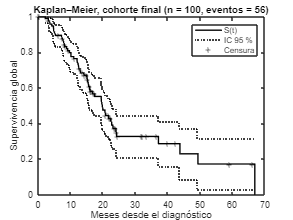


% Curva Kaplan–Meier global (con IC 95 % y marcas de censura)
[f, x, flo, fup] = ecdf(coh.tiempo_meses, 'Censoring', coh.evento == 0, 'Function', 'survivor');
fig = figure('Name','KM global');
h1 = stairs(x, f, 'k', 'LineWidth', 1.5); hold on;
h2 = stairs(x, flo, 'k:'); stairs(x, fup, 'k:');
[xu, iu] = unique(x, 'last');
tc = coh.tiempo_meses(coh.evento == 0);
h3 = plot(tc, interp1(xu, f(iu), tc, 'previous', 'extrap'), 'k+', 'MarkerSize', 6);
ylim([0 1]); xlabel('Meses desde el diagnóstico'); ylabel('Supervivencia global');
title(sprintf('Kaplan–Meier, cohorte final (n = %d, eventos = %d)', height(coh), nEv));
legend([h1 h2 h3], ["S(t)","IC 95 %","Censura"], 'Location', 'northeast'); hold off;
exportgraphics(fig, fullfile(carpetaSal, "QC_KM_global.png"), 'Resolution', 300);

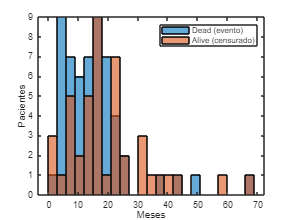


fig = figure('Name','Tiempos de seguimiento');
histogram(coh.tiempo_meses(coh.evento == 1), 0:3:max(coh.tiempo_meses)+3); hold on;
histogram(coh.tiempo_meses(coh.evento == 0), 0:3:max(coh.tiempo_meses)+3); hold off;
legend(["Dead (evento)","Alive (censurado)"]); xlabel('Meses'); ylabel('Pacientes');
title('Distribución de tiempos');
exportgraphics(fig, fullfile(carpetaSal, "QC_tiempos.png"), 'Resolution', 300);

### Sección 14. QC de la expresión de los genes de interés.

Esta sección es el control de calidad de la expresión de los genes del panel en la cohorte final. Su objetivo es comprobar, antes del análisis de supervivenica, que los genes estén bien expresados, que no haya valores extremos que distorsionen los resultados y que se pueda saber qué tan relacionados están entre sí. 

Primero toma de la cohorte la matriz "x", con los valores de TPM de cada gen (una fila por paciente y una columna por gen). A partir de ella calcula dos versiones. "L" es la expresión transformada con log2(TPM + 1), la escala que se usa en el análisis. El logaritmo reduce la asimetría típico de los datos de expresión, donde unos pocos pacientes tienen valores muy altos, y sumar 1 evita el logritmo de cero. "Z" es esa misma expresión estandarizada: a cada gen se le resta su media y se divide entre su desviación estándar, de modo que cada valor indica a cuántas desviaciones estándar está la media de ese gen.

Con estas matrices construye la tabla "QC_expr", con una fila por gen y tres indicadores: 

- **Mediana de TPM: **qué tan expresado está el gen en la cohorte. 

- **Porcentaje de muestras con TPM menor a 1**: en cuántos pacientes el gen está prácticamente apagado. 

- **Número de valores atípicos: **pacientes cuyo valor está a más de 3 desviaciones estándar de la media. 

Si alguno de los genes tiene TPM menor a "q" en más de la mitad de las muestras, el script muestra una advertencia. En ese caso, dividir a los pacientes por la mediana para las curvas de Kaplan-Meier no tendría sentido, porque el grupo de "expresión baja" estaría formado casi solo por ceros. 

Después genera dos figuras: 

- **QC_expresion:boxplot.png:** Un diagrama de caja por gen con su distribución en escala log2(TPM+1). Muestra el nivel de expresión de cada gen, cuánto varía entre pacientes (la altura de la caja) y los valores extremos. Los genes con poca variación tienen menos poder para separar a los pacientes en grupos. 

- **QC_correlacion_genes.png: **Un mapa de calor con la correlación de Spearman entre cada par de genes, de -1(azul) a 1 (amarillo). Sirve para detectar colinealidad: Si dos genes estuvieran muy correlacionados (por encima de 0.70), no deberían entrar juntos a un mismo modelo de Cox, porque sus efectos se confundirían.

X = coh{:, genes};               % TPM
L = log2(X + 1);                 % escala para el análisis
Z = (L - mean(L)) ./ std(L);

QC_expr = table(genes', median(X)', 100*mean(X < 1)', sum(abs(Z) > 3)', ...
    'VariableNames', ["gen","TPM_mediana","pct_TPM_menor_1","n_atipicos_z3"]);
fprintf("\nQC de expresión (cohorte final):\n");


QC de expresión (cohorte final):


disp(QC_expr);

      gen       TPM_mediana    pct_TPM_menor_1    n_atipicos_z3
    ________    ___________    _______________    _____________

    "PDGFRB"      137.02              0                 2      
    "CREB1"       11.587              0                 1      
    "RB1"         26.226              0                 1      
    "RICTOR"      9.2043              0                 1      
    "MAPK7"        12.18              0                 1      
    "STAT3"       73.518              0                 1      
    "MTSS1"       10.341              0                 0      
    "PTPN11"      43.284              0                 1      
    "SRC"         75.723              0                 1      



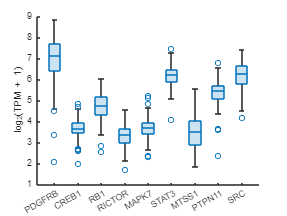

bajo = QC_expr.gen(QC_expr.pct_TPM_menor_1 > 50);
if ~isempty(bajo)
    warning("Genes con TPM < 1 en más de la mitad de las muestras (dividir por mediana no es informativo): %s", ...
            strjoin(bajo, ", "));
end

fig = figure('Name','QC expresión');
boxchart(L); xticklabels(genes);
ylabel('log_2(TPM + 1)'); 
title('Expresión de los genes de interés');
exportgraphics(fig, fullfile(carpetaSal, "QC_expresion_boxplot.png"), 'Resolution', 300);

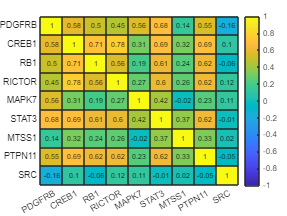


R = corr(L, 'Type', 'Spearman');
fig = figure('Name','Correlación entre genes');
heatmap(genes, genes, round(R, 2), 'Colormap', parula, 'ColorLimits', [-1 1]);
title('Correlación de Spearman entre genes (colinealidad para el Cox multivariado)');
exportgraphics(fig, fullfile(carpetaSal, "QC_correlacion_genes.png"), 'Resolution', 300);

### Sección 15. Guardar los resultados generados. 

Esta última sección guarda los resultados del script en la carpeta de resultados (Resultados_Supervivencia) definida en la sección 1. Lo más importante que guarda es la cohorte final, que es el archivo de entrada para el script de Kaplan-Meier y Cox univariado por gen y multivariado (PAAD_supervivencia_KM_Cox). 

Primero agrega a la cohorte la expresión transformada de cada gen. En la sección 14 se calculó la matriz "L", y aquí cada columna de esa matriz se guarda en la tabla "coh" con el nombre del gen precedido por "log2_". El prefijo sirve para dos cosas: deja claro que esos valores están en escala logarítmica y no en TPM, y permite que el script de Kaplan-Meier y Cox identifiquen automáticamente las columnas de expresion, porque busca las que empiezan con "log2_". 

Después se eligen las columnas que se guardarán y se crea la tabla "Cohorte_OS", con una fila por paciente. Sus columnas son: 

- **Identificadores:** pacientes, barcode de la muestra y UUID del archivo. 

- **Variables de supervivencia: **tiempo en días y en meses, evento y estado vital. 

- **Variables clínicas:** causa de muerte, edad, estadio (completo y agrupado), pureza, diagnóstico y morfología. 

- Expresión de los genes en log2(TPM+1). 

Las columnas intermedias que solo se usaron durante el filtrado, como el tipo de muestra, los días de muerte y de seguimiento por separado o los 15 caracteres del barcode, no se incluyen. Así la tabla queda limpia. 

Luego se guardan cuatro archivos ".csv", que pueden abrirse en Excel, R o Python: 

- **Cohorte_supervivencia_OS.csv:** la cohorte final. Es la entrada del análsis de supervivencia por gen (Parte 2). 

- **Bitacora_filtros.csv: **Cuántos perfile y pacientes quedaron después de cada filtro Es la base del diagrama de flujo. 

- **Pacientes_excluidos,csv:** Cada paciente eliminado, con su barcode y el motivo,

- **QC_expresion.csv:** Los indicadores de calidad de cada gen (mediana de TPM, porcentaje de muestras con TPM menor a 1 y valores atípicos). 

Además, se guarda el archivo "Cohorte_supervivencia_OS.mat" con esas mismas cuatro tablas y la lista de genes, en formato nativo de MATLAB. Se puede recargar con "load" sin volver a correr el script. 

Por último, el script imprime un mensaje que confirma que terminó y en que carpeta quedaron los archivos. Las figuras de control de calidad no se guardan aquí: cada una se guarda en la misma carpeta en el momento en que se generó, en las secciones 8, 13 y 14.  

for k = 1:numel(genes), coh.("log2_" + genes(k)) = L(:, k); end

colsSal = ["paciente","sample_barcode","file_uuid","tiempo_dias","tiempo_meses","evento", ...
           "vital_status","causa_muerte","edad","estadio","estadio_grupo","pureza", ...
           "diagnostico","morfologia", "log2_" + genes];
Cohorte_OS = coh(:, colsSal);

writetable(Cohorte_OS, fullfile(carpetaSal, "Cohorte_supervivencia_OS.csv"));
writetable(bitacora,   fullfile(carpetaSal, "Bitacora_filtros.csv"));
writetable(excluidos,  fullfile(carpetaSal, "Pacientes_excluidos.csv"));
writetable(QC_expr,    fullfile(carpetaSal, "QC_expresion.csv"));
save(fullfile(carpetaSal, "Cohorte_supervivencia_OS.mat"), ...
     "Cohorte_OS", "bitacora", "excluidos", "QC_expr", "genes");

fprintf("\nListo. Archivos guardados en: %s\n", carpetaSal);


Listo. Archivos guardados en: C:\PAP Keyla Otoño 2026\Downloaded_Data_Cohort_Pancreas\Resultados_Supervivencia



%% ===================== Funciones locales =====================
function T = leerTSVtexto(ruta)
% Lee un .tsv con todas las columnas como texto y conserva los nombres originales
    opts = detectImportOptions(ruta, 'FileType','text', 'Delimiter','\t', ...
                               'VariableNamingRule','preserve');
    opts = setvartype(opts, opts.VariableNames, 'string');
    T = readtable(ruta, opts);
end

function x = limpiar(x)
% Convierte los vacíos de GDC ('--, Not Reported, Unknown) en <missing>
    x = strtrim(string(x));
    x(ismissing(x) | x == "" | x == "'--" | x == "--" | ...
      lower(x) == "not reported" | lower(x) == "unknown") = missing;
end

function v = primerValor(x)
% Primer valor no faltante de un grupo de filas
    x = x(~ismissing(x));
    if isempty(x), v = string(missing); else, v = x(1); end
end

function [T, excl, bit] = filtrar(T, conservar, paso, motivo, excl, bit)
% Aplica un filtro, registra a los excluidos y actualiza la bitácora
    nuevos = table(T.paciente(~conservar), T.sample_barcode(~conservar), ...
                   repmat(string(motivo), sum(~conservar), 1), ...
                   'VariableNames', ["paciente","sample_barcode","motivo"]);
    excl = [excl; nuevos];
    T = T(conservar, :);
    bit(end+1,:) = {string(paso), height(T), numel(unique(T.paciente))};
    fprintf("%-42s -> %4d perfiles | %4d pacientes (excluidos: %d)\n", ...
            paso, height(T), numel(unique(T.paciente)), sum(~conservar));
end

function m = medianaKM(t, censurado)
% Mediana de una curva Kaplan–Meier (NaN si la curva no cae por debajo de 0.5)
    [f, x] = ecdf(t, 'Censoring', censurado, 'Function', 'survivor');
    i = find(f <= 0.5, 1);
    if isempty(i), m = NaN; else, m = x(i); end
end

### Referencias Bibliográficas. 

[1] MATLAB. (2026). *What Is Survival Analysis?* [https://la.mathworks.com/help/stats/survival-analysis.html](https://la.mathworks.com/help/stats/survival-analysis.html)

[2] M. Mounir *et al.*, «New functionalities in the TCGAbiolinks package for the study and integration of cancer data from GDC and GTEx», *PLoS Computational Biology*, vol. 15, n.o 3, p. e1006701, mar. 2019, doi: 10.1371/journal.pcbi.1006701.

[3] J. Liu *et al.*, «An Integrated TCGA Pan-Cancer Clinical Data Resource to Drive High-Quality Survival Outcome Analytics», *Cell*, vol. 173, n.o 2, pp. 400-416.e11, abr. 2018, doi: 10.1016/j.cell.2018.02.052.